clc ; clear; close all;

# Hacer lo siguiente para el sistema de transmisión

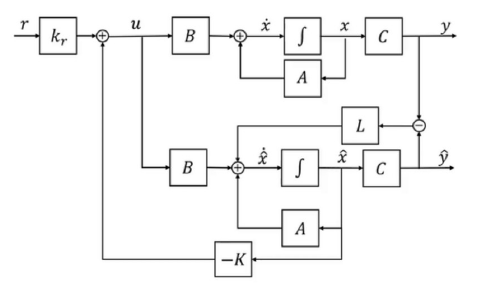

Jc = 6250;
Jf = 0.625;
ds = 1000;
cs = 75000;
GR = 57; % gear ratio

A  = [-ds/(Jf*GR^2) ds/(Jf*GR) -cs/(Jf*GR)
       ds/(Jc*GR)  -ds/(Jc)    cs/Jc
        1/GR           -1         0         ];
Bu = [1/Jf 0  0]';
Bd = [0 -1/Jc 0]';
Cp = [0   1   0];

#### Determine el polinomio deseado para un overshoot del 2% y un settling time de 1s para la variable de salida del sistema.

- Sistema objetivo

Mp      = 0.02;                     % overshoot
delta   = log(Mp);                  % decremento logaritmico
zeta    = 1/sqrt(1 + (pi/delta)^2); % amortiguamiento mínimo
Ts      = 1.0;                      % tiempo de asentamiento
wn      = -log(0.02)/(Ts*zeta);              % frecuencia natural
disp(zeta);

    0.7797



disp(wn);

    5.0173



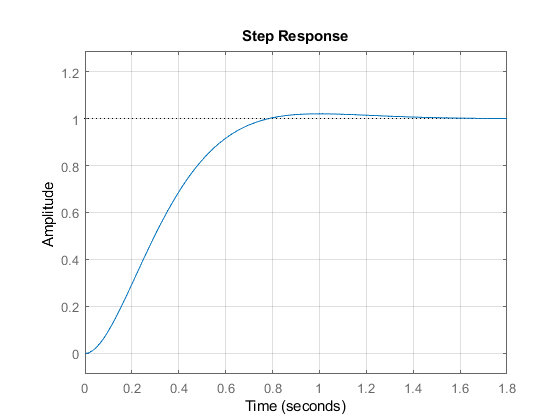

num     = wn^2;
den     = [1 2*zeta*wn wn^2];
sys     = tf(num, den);
step(sys); grid on; axis('equal')

stepinfo(sys)

ans = struct with fields:
        RiseTime: 0.4769
    SettlingTime: 0.7180
     SettlingMin: 0.9077
     SettlingMax: 1.0200
       Overshoot: 2.0000
      Undershoot: 0
            Peak: 1.0200
        PeakTime: 1.0006


- Sistema a lazo cerrado del controlador

[pControlador, ~]   = pzmap(sys);
pControlador        = [pControlador; -2*wn] % Polos a lazo cerrado del controlador

pControlador =   -3.9120 + 3.1416i
  -3.9120 - 3.1416i
 -10.0346 + 0.0000i


- Encuentre el valor de la matriz K.

K      = acker(A, Bu, pControlador)

K = 	1.0e+03 *

    0.0108    0.1370    1.8305


- Determine el valor de kr.

kr     = 1/(Cp*(-(A-Bu*K)\Bu))

kr = 749.9283

- Cierre el bucle de control a través del observador.

pObservador = pControlador(3)*5*ones(3, 1);
L           = acker(A.', Cp.', pObservador); % En realidad se determina L^t
L           = L.'

L = 	1.0e+05 *

    5.7365
    0.0015
    0.0048


- Grafique las variables de interés del sistema

d = 1000; % disturbance
sim('Driveline_ctrl_sim');
% VALORES REALES
tEngineSpeedMonitor   = EngineSpeedMonitor.time;
EngineSpeed           = EngineSpeedMonitor.signals.values;

tWheelSpeedMonitor    = WheelSpeedMonitor.time;
WheelSpeed            = WheelSpeedMonitor.signals.values;

tTorqueMonitor        = TorqueMonitor.time;
Torque                = TorqueMonitor.signals.values;

tControlSignalMonitor = ControlSignalMonitor.time;
ControlSignal         = ControlSignalMonitor.signals.values;

% ESTIMACIONES
tEngineSpeedMonitorEst   = EngineSpeedMonitorEst.time;
EngineSpeedEst           = EngineSpeedMonitorEst.signals.values;

tWheelSpeedMonitorEst    = WheelSpeedMonitorEst.time;
WheelSpeedEst            = WheelSpeedMonitorEst.signals.values;

tTorqueMonitorEst        = TorqueMonitorEst.time;
TorqueEst                = TorqueMonitorEst.signals.values;


## RESULTADOS

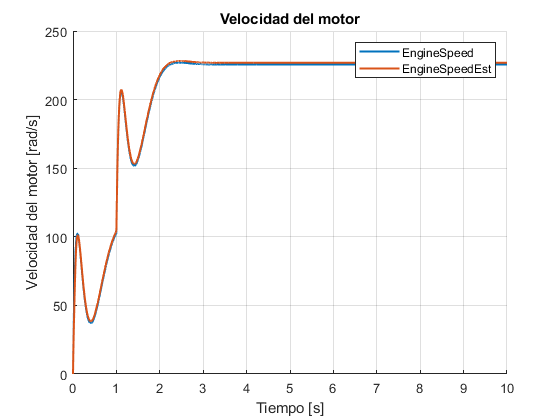

figure;hold on;
plot(tEngineSpeedMonitor, EngineSpeed, 'LineWidth', 1.5);
plot(tEngineSpeedMonitorEst, EngineSpeedEst, 'LineWidth', 1.5);
legend('EngineSpeed', 'EngineSpeedEst')
xlabel('Tiempo [s]');
ylabel('Velocidad del motor [rad/s]');
title('Velocidad del motor');
grid on;

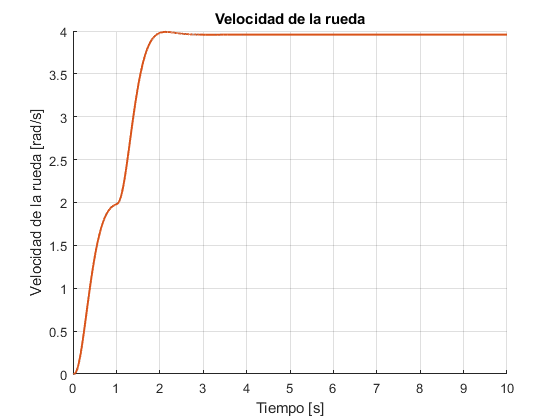


figure;hold on;
plot(tWheelSpeedMonitor, WheelSpeed, 'LineWidth', 1.5);
plot(tWheelSpeedMonitorEst, WheelSpeedEst, 'LineWidth', 1.5);
xlabel('Tiempo [s]');
ylabel('Velocidad de la rueda [rad/s]');
title('Velocidad de la rueda');
grid on;

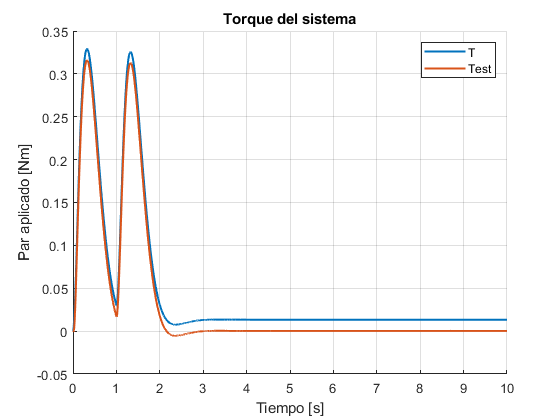


figure;hold on;
plot(tTorqueMonitor, Torque, 'LineWidth', 1.5);
plot(tTorqueMonitorEst, TorqueEst, 'LineWidth', 1.5);
legend('T','Test');
xlabel('Tiempo [s]');
ylabel('Par aplicado [Nm]');
title('Torque del sistema');
grid on;

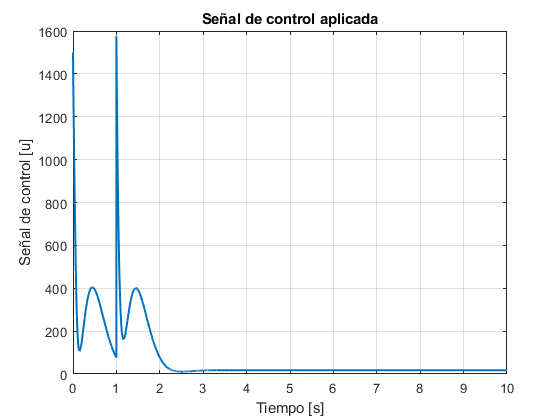


figure;
plot(tControlSignalMonitor, ControlSignal, 'LineWidth', 1.5);
xlabel('Tiempo [s]');
ylabel('Señal de control [u]');
title('Señal de control aplicada');
grid on;